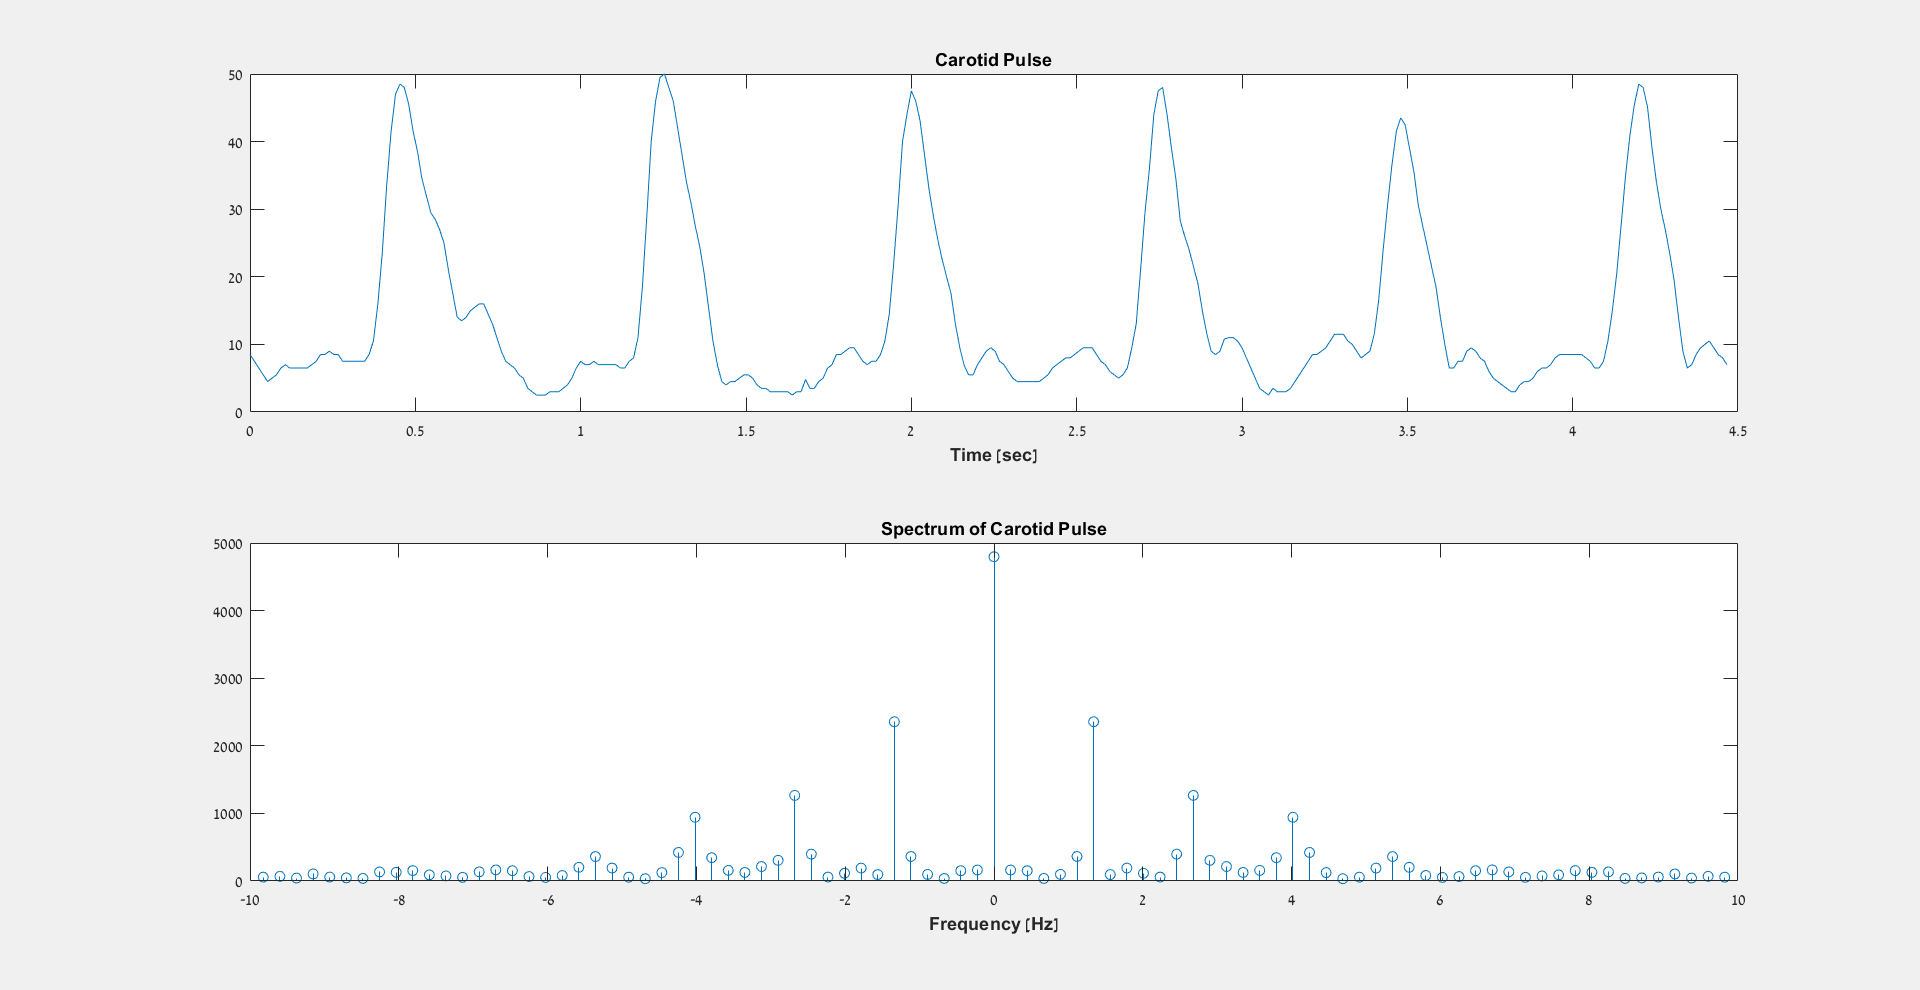

clc; clear

% Display the signal in time and frequency

fs=75;
load ('carotid.mat');
N=length(CP);

figure("name","Carotid Pulse 1","Position",get(0,'ScreenSize'),"Visible","on");
dt=1/fs;
time=linspace(0,(N-1)*dt,N);
subplot(2,1,1);
plot(time,CP);
title('Carotid Pulse');
xlabel('Time [sec]',"FontWeight","bold");
subplot(2,1,2);
f= linspace(-fs/2,(fs/2)-(fs/N),N);
stem(f,abs(fftshift(fft(CP))));
xlim([-10,10]);
ylim([0,5000]);
title('Spectrum of Carotid Pulse');
xlabel('Frequency [Hz]',"FontWeight","bold");

% Calculating the heart rate in the time plane

[pks, locs]=findpeaks(CP,fs,'MinPeakHeight',max(CP)/2);
mean_locs=mean(diff(locs));
BPM=60/mean_locs;

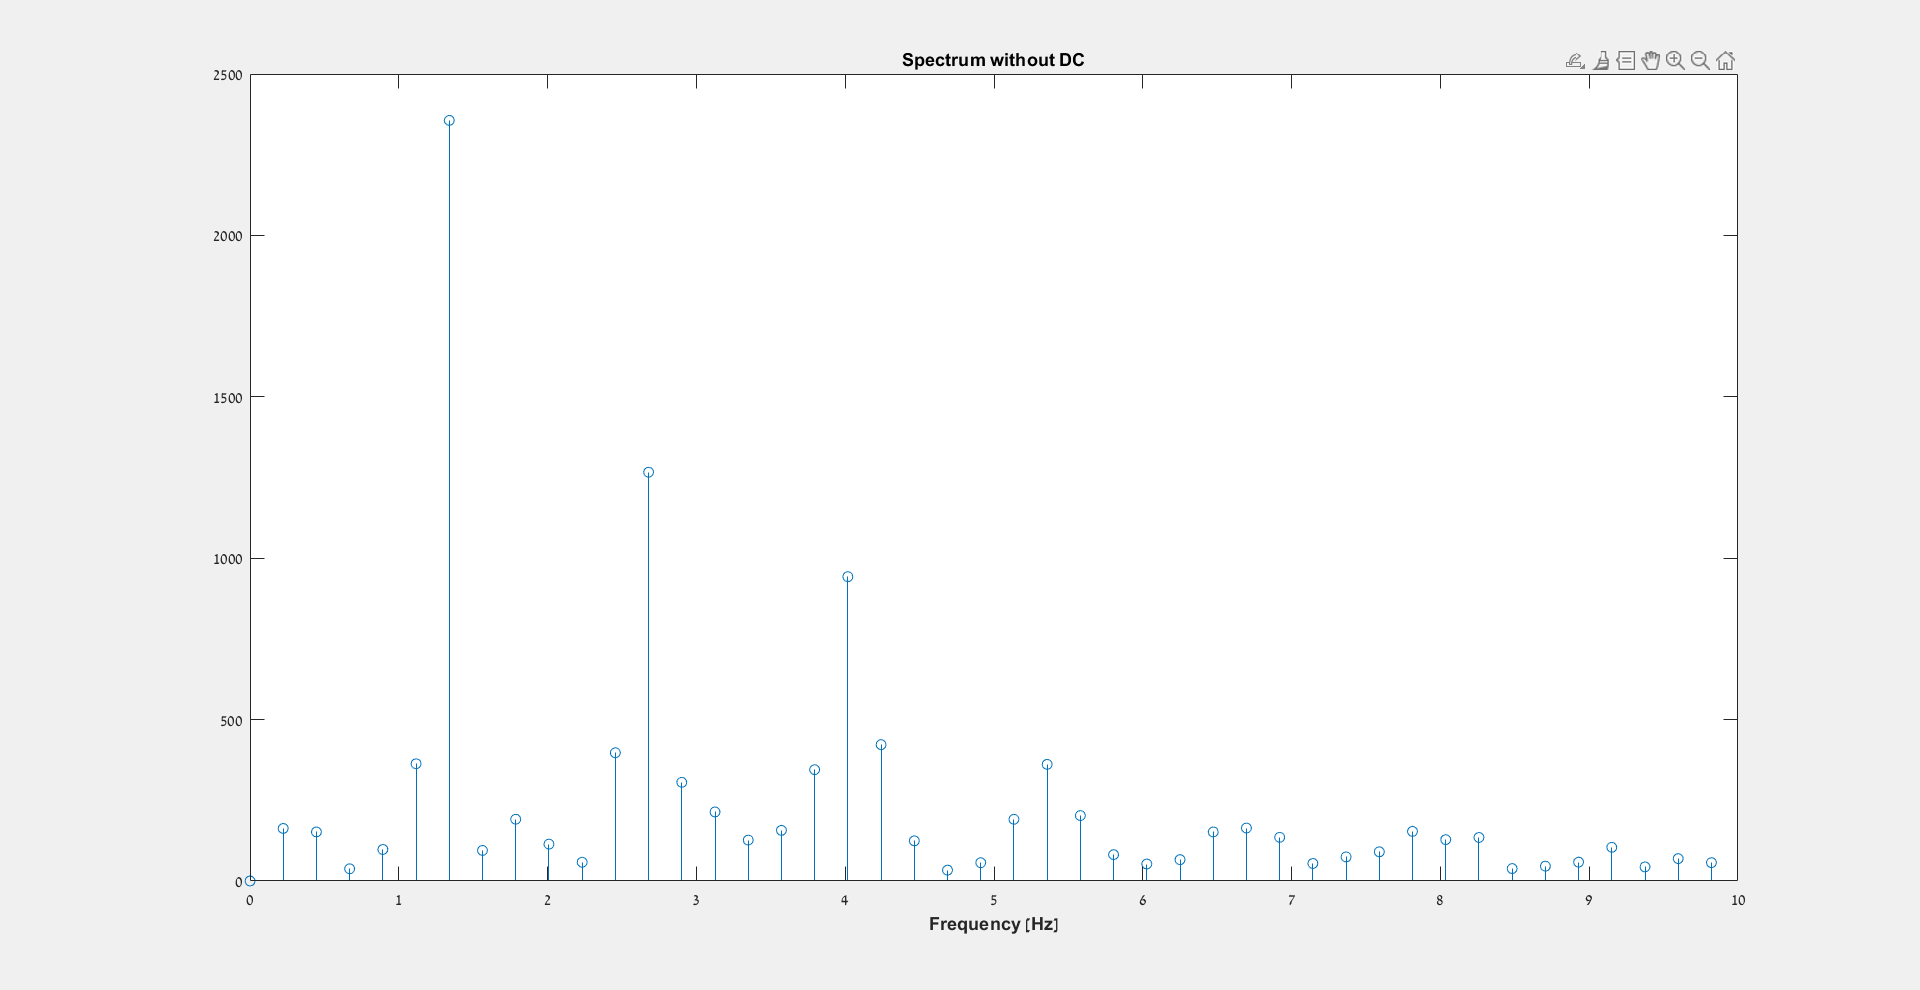

% Calculation of heart rate in the frequency plane

mean_CP=mean(CP);
CP_fft=abs(fft(CP-mean_CP));
CP_fft(N/2:end)=0;

figure("name","Carotid Pulse 2 - Spectrum","Position",get(0,'ScreenSize'),"Visible","on");
f_3=linspace(0,fs-(fs/N),N);
stem(f_3,CP_fft);
xlim([0,10]);
%ylim([0,2500]);
title('Spectrum without DC');
xlabel('Frequency [Hz]',"FontWeight","bold");

max_CP_fft=max(CP_fft);
BPM_New=f_3(CP_fft==max_CP_fft)*60;
